# World's Longest Tunnels

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

europe = ["Austria" "Belarus" "Finland" "France/Italy",...
    "Germany" "Greece" "Hungary" "Italy" "Norway",...
    "Poland" "Portugal" "Russia" "Spain" "Sweden",...
    "Switzerland" "Switzerland/France" "Switzerland/Italy",...
    "Ukraine" "United Kingdom" "United Kingdom/France"];
na = ["Canada" "United States"];
sa = "Peru";
asia = ["China" "India" "Japan" "Singapore",...
    "South Korea" "Taiwan" "Thailand" "Turkey"];
africa = "South Africa";

## Task 1

The `longTunnels.txt` file contains information about `tunnels` in use around the world that are at least 13 km long.

tunnels = readtable("./data/longTunnels.csv", "TextType", "string");

## Task 2

The [`histogram`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) function can bin on integer values. Use the `BinMethod` property name and specify the value as `"integers"`.

`histogram``(``data``,``"BinMethod"``,``"integers"``)`

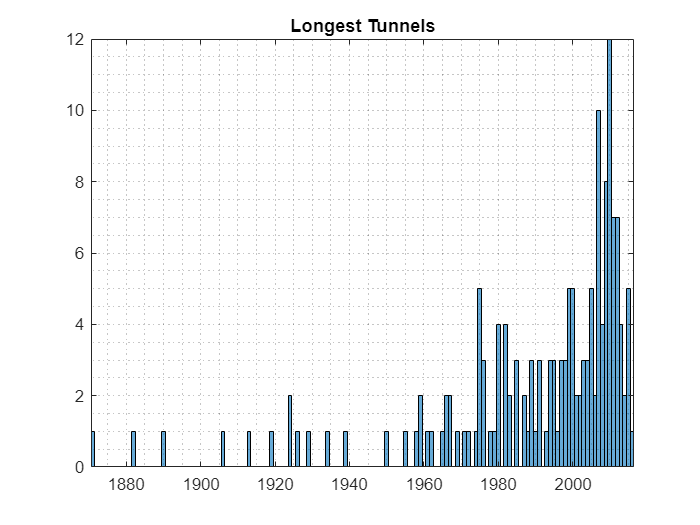

histogram(tunnels.Year, "BinMethod", "integers")
grid minor
axis tight
title("Longest Tunnels")

## Task 3

Many different types of `tunnels` are represented in the `Type` variable of `tunnels`.

tunnels.Type = categorical(tunnels.Type);
types = categories(tunnels.Type)

types = 4×1 cell array
    {'Metro'               }
    {'Particle Accelerator'}
    {'Railway'             }
    {'Road'                }


pa = tunnels(tunnels.Type == "Particle Accelerator", :)

pa = 2×6 table
              Name                      Location                   Region           Length            Type            Year
    ________________________    ________________________    ____________________    ______    ____________________    ____

    "LEP Tunnel"                "CERN"                      "Switzerland/France"    26659     Particle Accelerator    1989
    "UNK proton accelerator"    "Protvino (near Moscow)"    "Russia"                21000     Particle Accelerator    1994


## Task 4

The `Region` variable in `tunnels` contains the country or region in which the tunnel can be found.

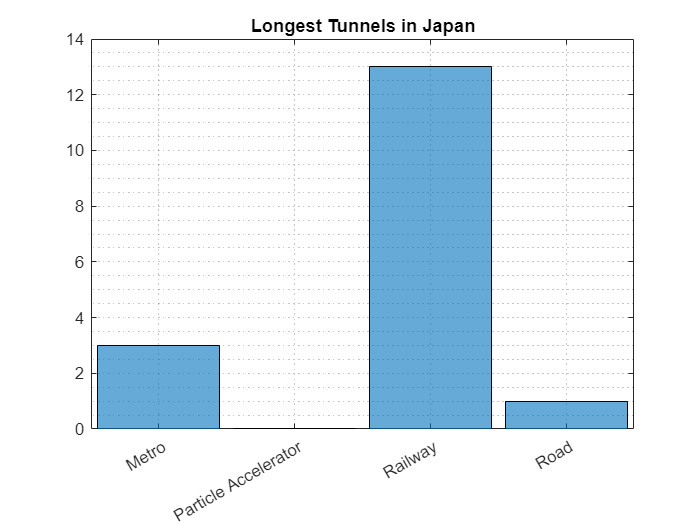

tunnels.Region = categorical(tunnels.Region);
histogram(tunnels.Type(tunnels.Region=="Japan"))
grid minor
title("Longest Tunnels in Japan")

## Task 5

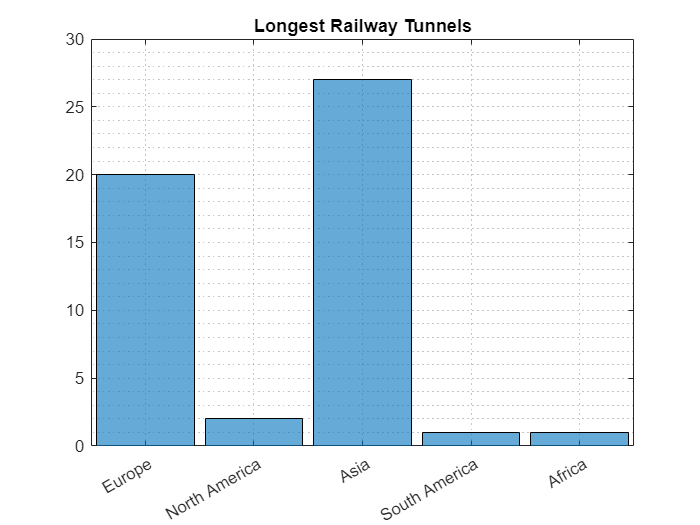

tunnels.Continent = mergecats(tunnels.Region, europe, "Europe");
tunnels.Continent = mergecats(tunnels.Continent, na, "North America");
tunnels.Continent = mergecats(tunnels.Continent, sa, "South America");
tunnels.Continent = mergecats(tunnels.Continent, asia, "Asia");
tunnels.Continent = mergecats(tunnels.Continent, africa, "Africa");
histogram(tunnels.Continent(tunnels.Type == "Railway"))
grid minor
title("Longest Railway Tunnels")